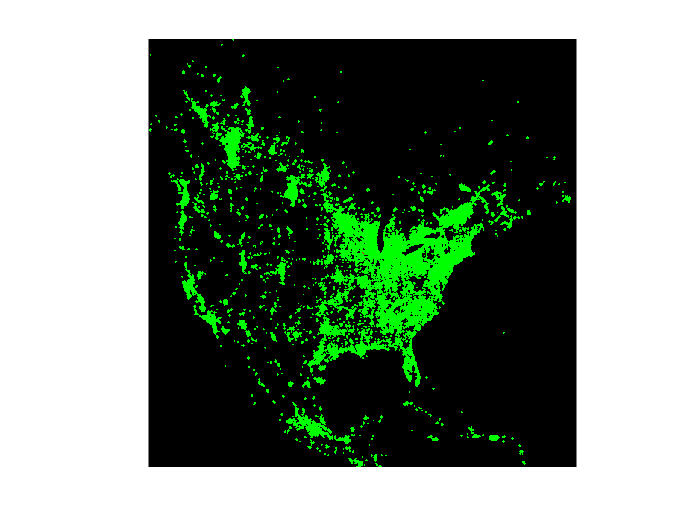

figure;%利用当前属性创建窗格
f0=0.05;%正常人的感染率
f1=0.001;%感染者的死亡率
f2=0.1;%感染者在没有死亡下的治愈率
f3=0.02;%治愈者再次被感染的几率
axes;%建立坐标轴
rand('state',0);
%这个命令应该是回到最开始的种子，
%否则森林的状态在你第二次运行的时候是接着上一次运行的结果
%不是一个新的状态
set(gcf,'DoubleBuffer','on');
%设置的目的是为了防止在不断循环画动画的时候会产生闪烁的现象
% S=round((rand(300)/2+0.5)*2);
% S=ones(1000);%设置人群
S=dlmread("img_binary.txt");%使用相对路径
S(500,500)=2;
%设置初始感染者位置
Sk=zeros(1002);%初始化Sk矩阵
Sk(2:1001,2:1001)=S;%%加边开始的人群边界，人群的边界为一列或者一行
%将其人群的部分插入这个矩阵中
% 红色表示已经感染的人(S中等于2的位置)
% 绿色表示正常人(S中等于1的位置)
% 黑色表示死亡人(S中等于0的位置)
C=zeros(1002,1002,3);%构造一个302*302*3的张量（数组）
R=zeros(1000);%初始化R矩阵
G=zeros(1000);%初始化G矩阵
R(S==2)=1;%构成的向量的一个位置上对应的数为2，则给R赋值1
G(S==1)=1;%构成的向量的一个位置上对应的数为1，则给R赋值1

C(2:1001,2:1001,1)=R;%将C的第一层赋值为R矩阵
C(2:1001,2:1001,2)=G;%将C的第二层赋值为G矩阵
%%%%新增%%%%%%%
latitude(0.001,1002)%纬度影响的权重，整体维数大小
%%%%新增%%%%%%%
load("latitude_fix.mat")

t=0;%初始化时间
while t<10000
    
    t=t+1;
    St=Sk;%St表示t时刻的人群情况，Sk矩阵代表着初始设定的人群情况
    Su=zeros(1002);%初始化Su矩阵
    Sf=Sk;%Sf初始化为Sk
    Sf(Sf<1.5)=0;%将人群中的死亡人和正常人的点去掉，只留下感染人
    Sf=Sf/2; %感染人变为1，此处Sf只有感染和空格两种

    
%%%%新增%%%%%%%
    f0_season=f0+season(0.01,t,10000,2);%当前时间，总仿真步长，模拟的年限
    
    
    % 用卷积代替原本的元胞扩散算法
    kernel=ones(15,15);
    Su=conv2(Sf,kernel,'same');
%     Su(3:998,3:998) = Sf(1:996,1:996) + Sf(1:996,2:997) + Sf(1:996,3:998) + Sf(1:996,4:999) + Sf(1:996,5:1000) + ...
%                   Sf(2:997,1:996) + Sf(2:997,2:997) + Sf(2:997,3:998) + Sf(2:997,4:999) + Sf(2:997,5:1000) + ...
%                   Sf(3:998,1:996) + Sf(3:998,2:997) + Sf(3:998,3:998) + Sf(3:998,4:999) + Sf(3:998,5:1000) + ...
%                   Sf(4:999,1:996) + Sf(4:999,2:997) + Sf(4:999,3:998) + Sf(4:999,4:999) + Sf(4:999,5:1000) + ...
%                   Sf(5:1000,1:996) + Sf(5:1000,2:997) + Sf(5:1000,3:998) + Sf(5:1000,4:999) + Sf(5:1000,5:1000);
    %对于矩阵中的一个点来说，周围八个点只要有一个点大于0，那么这个点就要变成感染状态（Sf=2）
    %所以这个命令是将矩阵中的一个点的周围八个点的数相加，这个数值就是周围八个点感染人的个数
    Sw=zeros(1002);%初始化Sw矩阵
    Sw(Su>0.5 & Sk==1)=1;%在Sw矩阵中将可能感染的人标记出来
    St(Su>0.5 &Sk==1)=0;%将St中的可能感染者的位置清零
    I0=rand(1002);%建立随机矩阵I0

%%%%新增%%%%%%%
    I0=I0+latitude_fix;

%%%%新增%%%%%%%
    St=St+Sw.*((I0<f0_season).*2+(I0>f0_season));
    %（I0<f0）.*2指的是在前面这个随机矩阵的元素小于f0时输出2
    %否则输出1
    %这也说明有f0的几率，正常人会感染
    %更新St
    
    
    Sg=zeros(1002);
    Sg(Su>0.5& Sk==1.1)=1;
    St(Su>0.5& Sk==1.1)=0;
    I1=rand(1002);
    St=St+Sg.*((I1<f3).*2+(I1>f3).*1.1);
    %治愈者有f3的概率再次感染,这里的做法和上面类似
    %同时更新St
  
     
    Sa=Sk(2:1001,2:1001);%Sf初始化为Sk
    Sa(Sa<1.5)=0;%将人群中的死亡人和正常人的点去掉，只留下感染人
    St(St==2& Sk==2)=0;%将St中感染者去掉
    St(2:1001,2:1001)=St(2:1001,2:1001)+Sa.*(rand(1000)>f1);
    %感染者有f1的概率死亡,这里的做法和上面类似
    %同时更新St
    
    Sc=Sk(2:1001,2:1001);%Sf初始化为Sk
    Sc(Sc<1.5)=0;%将人群中的死亡人和正常人的点去掉，只留下感染人
    Sc(St(2:1001,2:1001)==0)=0;%将St中死亡的人记录在Sc中
    St(St==2& Sk==2)=0;%将St中的现存感染者记为0
    I=rand(1000);%建立随机矩阵
    St(2:1001,2:1001)=St(2:1001,2:1001)+Sc.*((I<=f2).*0.55+(I>f2));
    %感染者有f2的概率被治愈，做法类似
    %同时更新St
    
       
    Sk=St; %更新t时刻的人群
    R=zeros(1002);%初始化R矩阵
    G=zeros(1002);%初始化G矩阵
    R(Sk==2)=1;%当Sk中标记为2的点，也是表示感染人则在R中标记出来
    G(Sk==1)=1;%当Sk中标记为1的点，也是表示正常人的点在G中标记出来
    G(Sk==1.1)=0.5;%当Sk中标记为1.1的点，也是表示免疫人，在G中标记
    C(:,:,1)=R;%把C的第一层赋值为R
    C(:,:,2)=G;%把C的第二层赋值为G
    
  imshow(C,'InitialMagnification','fit');
    pause(0.001);
end